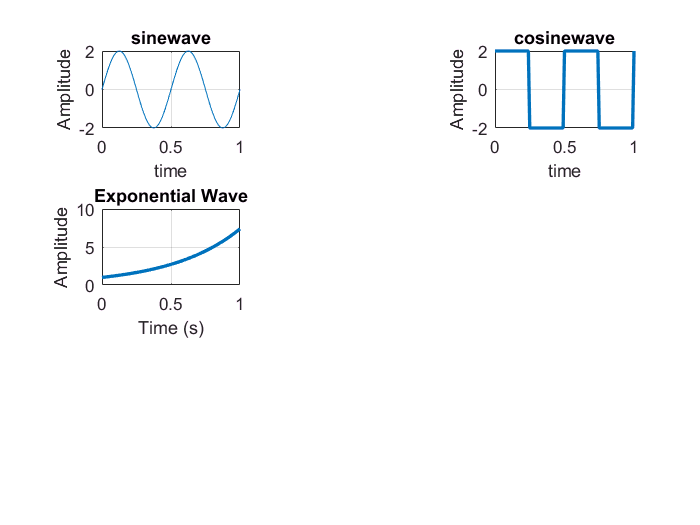

t=0:0.01:1;
a=2; 
subplot(3,3,1);
b=a*sin(2*pi*2*t);
plot(t,b); 
xlabel('time'); 
ylabel('Amplitude'); 
title('sinewave');
grid on;

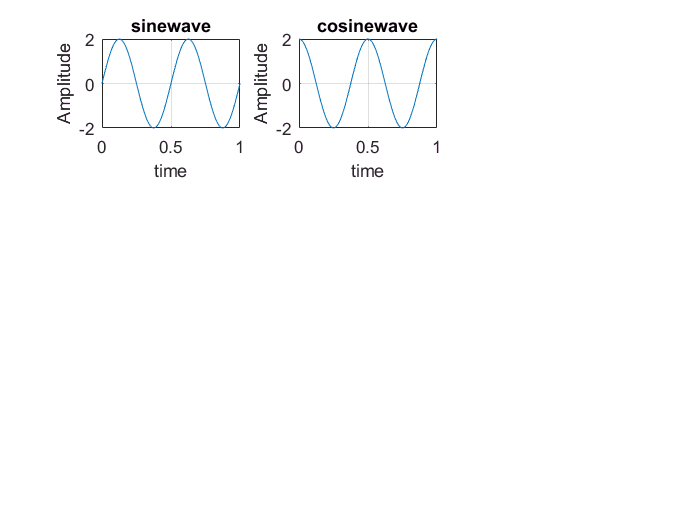

t=0:0.01:1;
a=2; 
subplot(3,3,2);
b=a*cos(2*pi*2*t);
plot(t,b); 
xlabel('time'); 
ylabel('Amplitude'); 
title('cosinewave');
grid on;

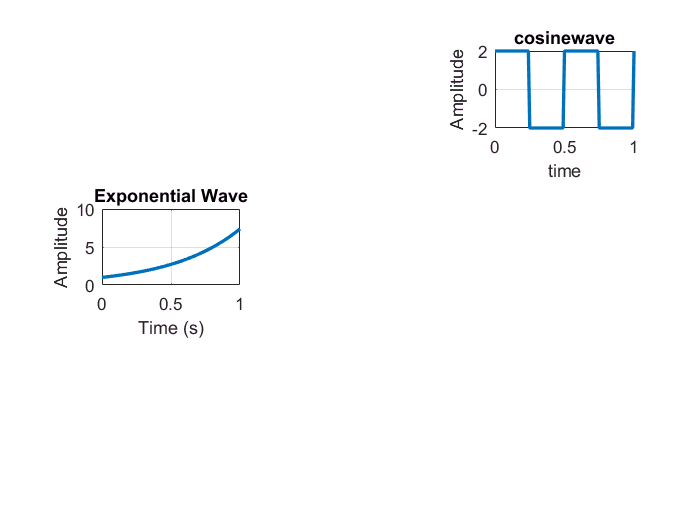

t=0:0.01:1;
a=2; 
subplot(3,3,3);
b=a*square(2*pi*2*t);
plot(t, b, 'LineWidth', 2); 
xlabel('time'); 
ylabel('Amplitude'); 
title('cosinewave');
grid on;

% Parameters for the exponential wave
amplitude = 1;       % Amplitude of the wave
decay_rate = -2;     % Decay rate of the exponential wave

% Time vector
t = 0:0.01:1;  % Time from 0 to duration with step size 1/sampling_rate

% Create the figure and subplot
          % Open new figure window
subplot(3,3,4);   % Create a subplot in a 3x3 grid at position 4

% Generate the exponential wave
exp_wave = amplitude * exp(-decay_rate * t);  % Exponentially growing wave since decay_rate is negative

% Plot the exponential wave in the subplot
plot(t, exp_wave, 'LineWidth', 2);  % Bold line
xlabel('Time (s)');
ylabel('Amplitude');
title('Exponential Wave');
grid on;

% Parameters for the sawtooth wave
amplitude = 1;     % Amplitude of the wave
frequency = 2;     % Frequency of the wave (Hz)
duration = 1;      % Duration of the signal (seconds)
sampling_rate = 1000; % Sampling rate (samples per second)

% Time vector
t = 0:1/sampling_rate:duration;  % Time from 0 to duration with step size 1/sampling_rate

% Generate the sawtooth wave
sawtooth_wave = amplitude * sawtooth(2 * pi * frequency * t);

% Plot the sawtooth wave
figure;
plot(t, sawtooth_wave, 'LineWidth', 2, 'Color', 'c');  % Cyan color
xlabel('Time (s)');
ylabel('Amplitude');
title('Sawtooth Wave');
grid on;


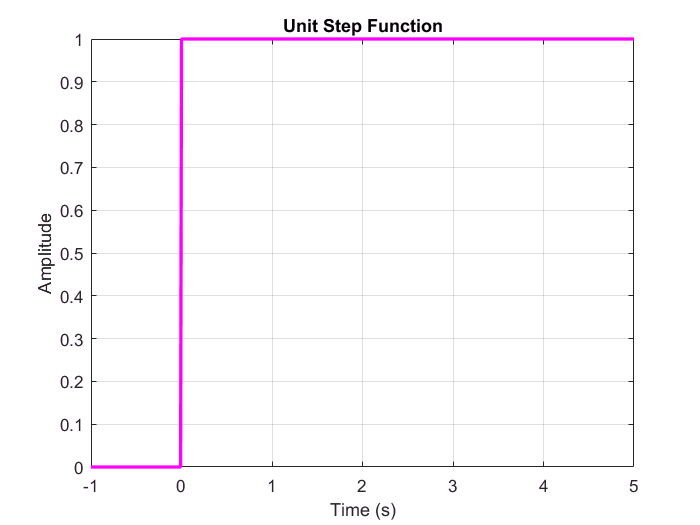

% Parameters for the unit step function
duration = 5;        % Duration of the signal (seconds)
sampling_rate = 100; % Sampling rate (samples per second)

% Time vector
t = -1:1/sampling_rate:duration;  % Time from -1 to duration with step size 1/sampling_rate

% Generate the unit step function
unit_step = t >= 0;  % Unit step function (1 for t >= 0, 0 otherwise)

% Plot the unit step function
figure;
plot(t, unit_step, 'LineWidth', 2, 'Color', 'm');  % Magenta color
xlabel('Time (s)');
ylabel('Amplitude');
title('Unit Step Function');
grid on;


% Adjust the axes for better visualization
%axis([-1 duration -0.5 1.5]);  % Set axis limits

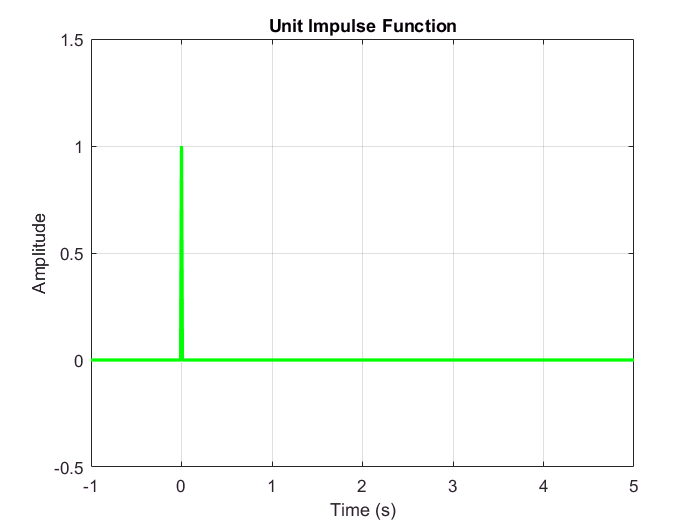

% Parameters for the unit impulse function
duration = 5;        % Duration of the signal (seconds)
sampling_rate = 100; % Sampling rate (samples per second)

% Time vector
t = -1:1/sampling_rate:duration;  % Time from -1 to duration

% Generate the unit impulse function
unit_impulse = zeros(size(t));      % Initialize the impulse array
unit_impulse(t == 0) = 1;            % Set value at t = 0 to 1

% Plot the unit impulse function
figure;
plot(t, unit_impulse, 'LineWidth', 2, 'Color', 'g');  % Magenta color
xlabel('Time (s)');
ylabel('Amplitude');
title('Unit Impulse Function');
grid on;

% Adjust the axes for better visualization
axis([-1 duration -0.5 1.5]);  % Set axis limits